BERNOULLI'S LEMNISCATE TRAJECTORY

close all
clear all

a = 5;
dt = 0.01;
Tf = 4*pi/(a+1);
t = 0:dt:Tf;
r1 = 0.1;
r2 = 1;
r_values = [r1, r2];

xd_all = zeros(2, length(t));   
yd_all = zeros(2, length(t));
thetad_all = zeros(2, length(t));
dxd_all = zeros(2,length(t));
dyd_all = zeros(2,length(t));
ddxd_all = zeros(2,length(t));
ddyd_all = zeros(2,length(t));
vd_all = zeros(2,length(t));
wd_all = zeros(2,length(t));
x0_all = zeros(2,1);
y0_all = zeros(2,1);
theta0_all = zeros(2,1);

for rr = 1:2
    r = r_values(rr);
    ok = false;

    omega = (a + 1) * t;
    xd = r * cos(omega) ./ (1 + sin(omega).^2);
    yd = (r * cos(omega) .* sin(omega)) ./ (1 + sin(omega).^2);
    dxd = gradient(xd, t);
    dyd = gradient(yd, t);
    thetad = atan2(dyd, dxd);
    ddxd = gradient(dxd, t);
    ddyd = gradient(dyd, t);
    vd = sqrt(dxd.^2 + dyd.^2);
    wd = (ddyd .* dxd - ddxd .* dyd) ./ vd.^2;

    xd_all(rr,:) = xd;
    yd_all(rr,:) = yd;
    dxd_all(rr,:) = dxd;
    dyd_all(rr,:) = dyd;
    ddxd_all(rr,:) = ddxd;
    ddyd_all(rr,:) = ddyd;
    thetad_all(rr,:) = thetad;
    vd_all(rr,:) = vd;
    wd_all(rr,:) = wd;

    % x0_all(rr,1) = xd(1) + r*(2*rand - 1);
    % y0_all(rr,1) = yd(1) + r*(2*rand - 1);
    % distance = sqrt( (xd(1) - x0_all(rr,1))^2 + (yd(1) - y0_all(rr,1))^2 );
    % ok = check(distance);
    % 
    % while (ok == false)
    %     x0_all(rr,1) = xd(1) + 0.5*(2*rand - 1);
    %     y0_all(rr,1) = yd(1) + 0.5*(2*rand - 1);
    %     distance = sqrt( (xd(1) - x0_all(rr,1))^2 + (yd(1) - y0_all(rr,1))^2 );
    %     ok = check (distance);
    % end
    % theta0_all(rr,1) = atan2(x0_all(rr,1), y0_all(rr,1));

    x0_all(1,1) = 0.075521;
    y0_all(1,1) = 0.0235941;
    theta0_all(1,1) = atan2(x0_all(1,1), y0_all(1,1));
    distance = sqrt( (xd(1) - x0_all(rr,1))^2 + (yd(1) - y0_all(rr,1))^2 );

    x0_all(2,1) = 0.719;
    y0_all(2,1) = -0.16359;
    theta0_all(2,1) = atan2(x0_all(2,1), y0_all(2,1));

    disp(['xd: ', num2str(xd(1)), '     x0: ', num2str(x0_all(rr,1))]);
    disp(['yd: ', num2str(yd(1)), '     y0: ', num2str(y0_all(rr,1))]);
    disp(['Distance for r = ', num2str(r), ': ', num2str(distance), 'm']);
end

xd: 0.1     x0: 0.075521


yd: 0     y0: 0.023594


Distance for r = 0.1: 0.033999m


xd: 1     x0: 0.719


yd: 0     y0: -0.16359


Distance for r = 1: 0.32515m


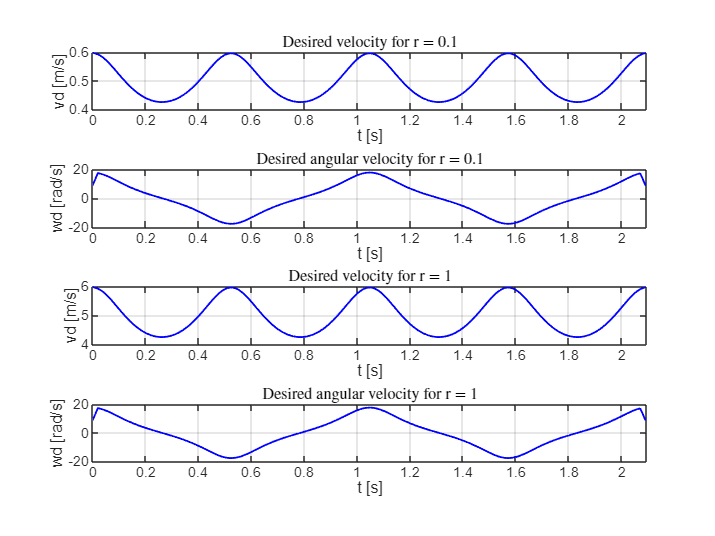


figure
subplot(4,1,1)
plot(t, vd_all(1,:), 'b', 'LineWidth', 1); hold on;
title(['Desired velocity for r = ', num2str(r1)],'Interpreter','latex');
xlabel('t [s]'); ylabel('vd [m/s]'); grid on; 
xlim([0 Tf]);
subplot(4,1,2)
plot(t, wd_all(1,:), 'b', 'LineWidth', 1); hold on;
title(['Desired angular velocity for r = ', num2str(r1)],'Interpreter','latex');
xlabel('t [s]'); ylabel('wd [rad/s]'); grid on; 
xlim([0 Tf]);
subplot(4,1,3)
plot(t, vd_all(2,:), 'b', 'LineWidth', 1); hold on;
title(['Desired velocity for r = ', num2str(r2)],'Interpreter','latex');
xlabel('t [s]'); ylabel('vd [m/s]'); grid on; 
xlim([0 Tf]);
subplot(4,1,4)
plot(t, wd_all(2,:), 'b', 'LineWidth', 1); hold on;
title(['Desired angular velocity for r = ', num2str(r2)],'Interpreter','latex');
xlabel('t [s]'); ylabel('wd [rad/s]'); grid on; 
xlim([0 Tf]);
set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, 'des_v_w_es3.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

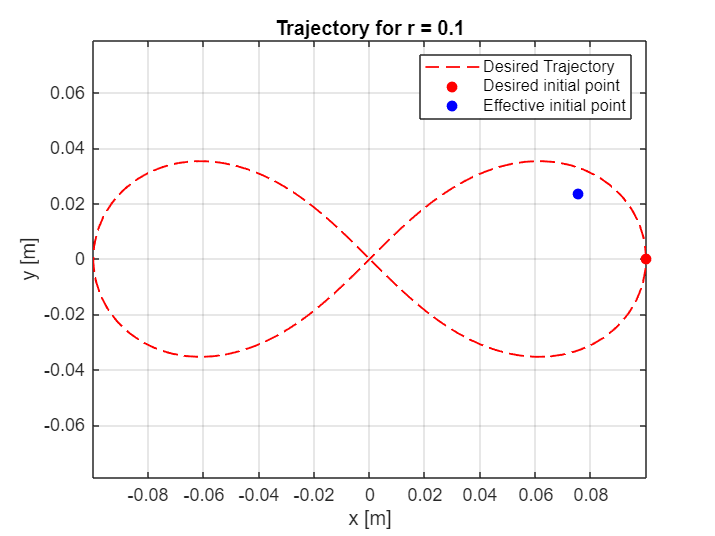


figure
plot(xd_all(1,:), yd_all(1,:), 'r--', 'LineWidth', 1); hold on;
title(['Trajectory for r = ', num2str(r1)]);
xlabel('x [m]'); ylabel('y [m]'); grid on; axis equal;
hold on
scatter(xd_all(1,1), yd_all(1,1), 'red', 'filled', 'o');
scatter(x0_all(1,1), y0_all(1,1), 'blue', 'filled', 'o');
grid on;
legend('Desired Trajectory', 'Desired initial point', 'Effective initial point');
set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, 'despath1.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

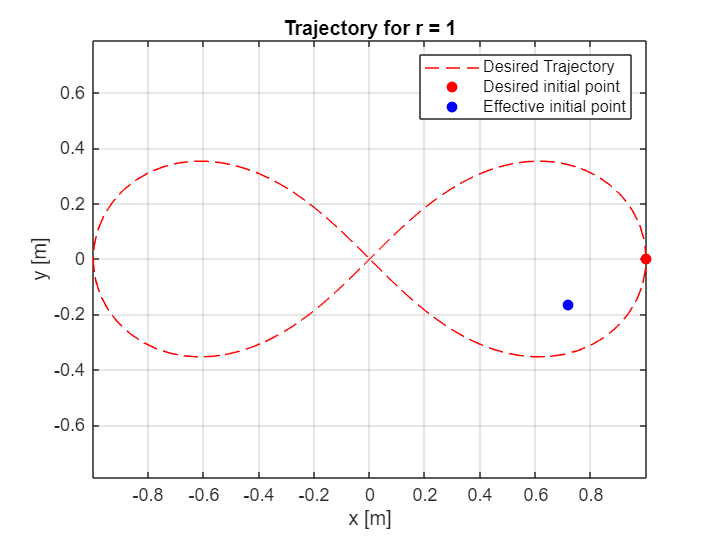

figure
plot(xd_all(2,:), yd_all(2,:), 'r--', 'LineWidth', 0.5); hold on;
title(['Trajectory for r = ', num2str(r2)]);
xlabel('x [m]'); ylabel('y [m]'); grid on; axis equal;
hold on
scatter(xd_all(2,1), yd_all(2,1), 'red', 'filled', 'o');
scatter(x0_all(2,1), y0_all(2,1), 'blue', 'filled', 'o');
grid on;
legend('Desired Trajectory', 'Desired initial point', 'Effective initial point');
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'despath2.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');



q0 = [x0_all(:,1), y0_all(:,1), theta0_all(:,1)]

q0 =     0.0755    0.0236    1.2680
    0.7190   -0.1636    1.7945


ref_xd1 = timeseries(xd_all(1,:), t);
ref_yd1 = timeseries(yd_all(1,:), t);
ref_thetad1 = timeseries(thetad_all(1,:), t);
ref_vd1 = timeseries(vd_all(1,:), t);
ref_wd1 = timeseries(wd_all(1,:), t);

ref_xd2 = timeseries(xd_all(2,:), t);
ref_yd2 = timeseries(yd_all(2,:), t);
ref_thetad2 = timeseries(thetad_all(2,:), t);
ref_vd2 = timeseries(vd_all(2,:), t);
ref_wd2 = timeseries(wd_all(2,:), t);

LINEAR CONTROLLER

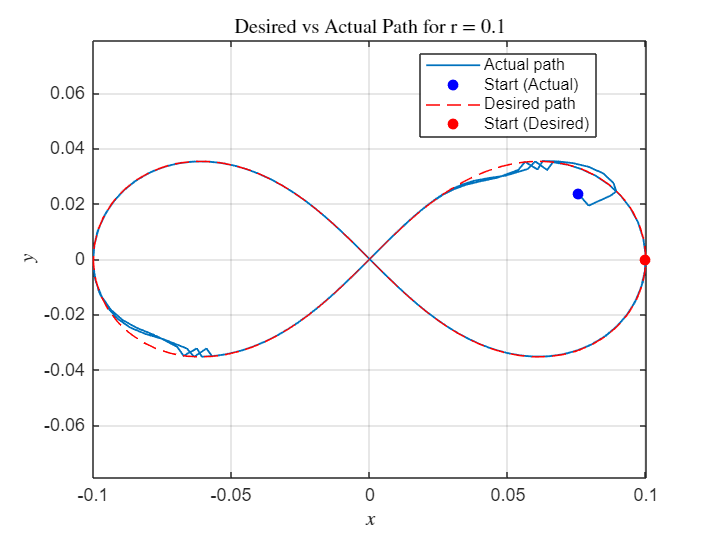

out = sim('ex3_linear_nonlinear_control.slx');

x1 = out.x_sim1.data;
y1 = out.y_sim1.data;
theta1 = out.theta_sim1.data;
v1 = out.v1.data;
w1 = out.w1.data;

gains1 = squeeze(out.gains1.data);
gains1_1 = gains1(1,:);
gains1_2 = gains1(2,:);
gains1_3 = gains1(3,:);

ex1 = out.ex_sim1.data;
ey1 = out.ey_sim1.data;
etheta1 = out.etheta_sim1.data;

x2 = out.x_sim2.data;
y2 = out.y_sim2.data;
theta2 = out.theta_sim2.data;
v2 = out.v2.data;
w2= out.w2.data;

gains2 = squeeze(out.gains2.data);
gains2_1 = gains2(1,:);
gains2_2 = gains2(2,:);
gains2_3 = gains2(3,:);

ex2 = out.ex_sim2.data;
ey2 = out.ey_sim2.data;
etheta2 = out.etheta_sim2.data;

%% r = 0.1

figure
plot(x1, y1, 'LineWidth', 1, 'DisplayName', 'Actual path');
hold on
scatter(x1(1), y1(1), 'blue', 'filled', 'DisplayName', 'Start (Actual)');
plot(xd_all(1,:), yd_all(1,:), 'r--', 'LineWidth', 0.5, 'DisplayName', 'Desired path');
scatter(xd_all(1,1), yd_all(1,1), 'red', 'filled', 'DisplayName', 'Start (Desired)');
xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
grid on
axis equal
legend('Location','best')
title('Desired vs Actual Path for r = 0.1','Interpreter','latex')
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'des_actual_1.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

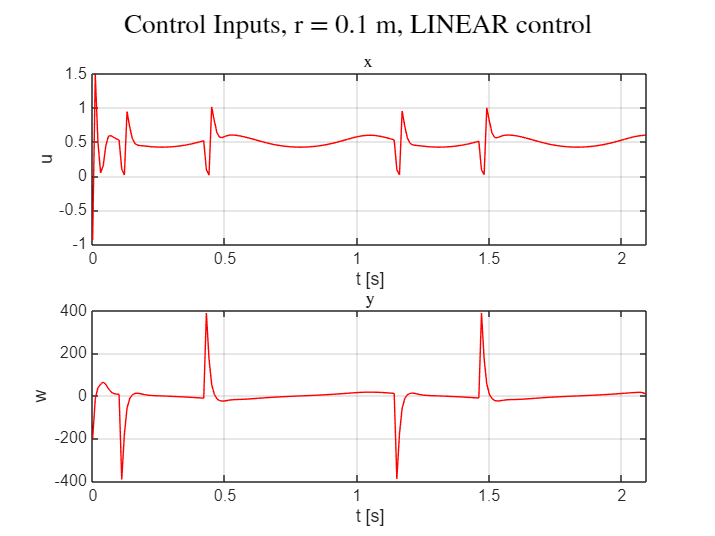


figure
sgtitle ('Control Inputs, r = 0.1 m, LINEAR control','Interpreter','latex')
subplot(2,1,1)
plot(t, squeeze(v1), 'r', 'LineWidth', 0.5); hold on;
title(' x ','Interpreter','latex');
xlabel('t [s]'); ylabel('u'); grid on; 
xlim([0 Tf]);
subplot(2,1,2)
plot(t, squeeze(w1), 'r', 'LineWidth', 0.5); hold on;
title('y','Interpreter','latex');
xlabel('t [s]'); ylabel('w'); grid on; 
xlim([0 Tf]);
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'inputs1.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

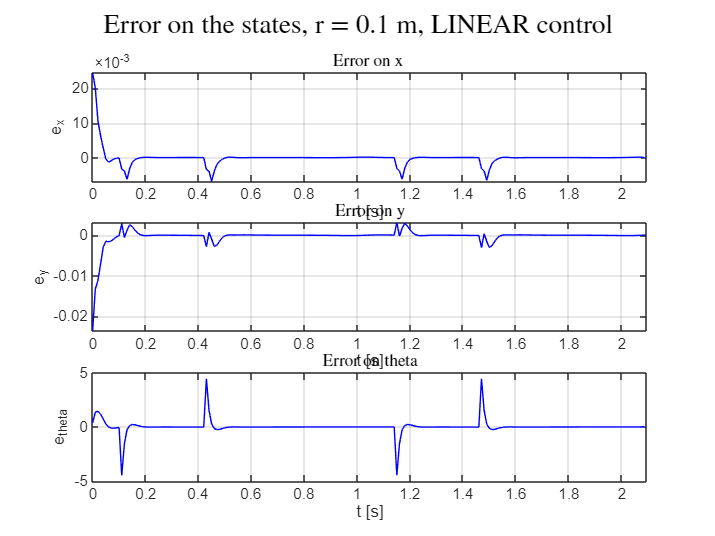


figure
sgtitle ('Error on the states, r = 0.1 m, LINEAR control','Interpreter','latex')
subplot(3,1,1)
plot(t, squeeze(ex1), 'b', 'LineWidth', 0.5); hold on;
title('Error on x ','Interpreter','latex');
xlabel('t [s]'); ylabel('e_x'); grid on; 
xlim([0 Tf]);
subplot(3,1,2)
plot(t, squeeze(ey1), 'b', 'LineWidth', 0.5); hold on;
title('Error on y','Interpreter','latex');
xlabel('t [s]'); ylabel('e_y'); grid on; 
xlim([0 Tf]);
subplot(3,1,3)
plot(t, squeeze(etheta1), 'b', 'LineWidth', 0.5); hold on;
title('Error on theta','Interpreter','latex');
xlabel('t [s]'); ylabel('e_{theta}'); grid on; 
xlim([0 Tf]);
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'error1.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

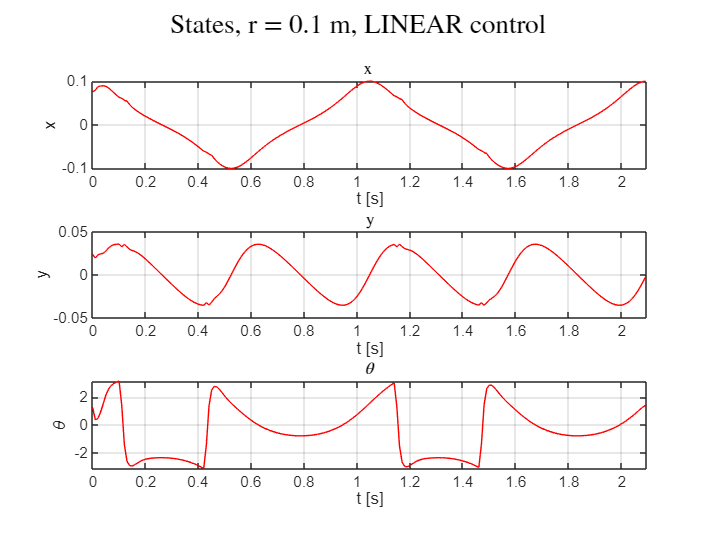


figure
sgtitle ('States, r = 0.1 m, LINEAR control','Interpreter','latex')
subplot(3,1,1)
plot(t, squeeze(x1), 'r', 'LineWidth', 0.5); hold on;
title(' x ','Interpreter','latex');
xlabel('t [s]'); ylabel('x'); grid on; 
xlim([0 Tf]);
subplot(3,1,2)
plot(t, squeeze(y1), 'r', 'LineWidth', 0.5); hold on;
title('y','Interpreter','latex');
xlabel('t [s]'); ylabel('y'); grid on; 
xlim([0 Tf]);
subplot(3,1,3)
plot(t, squeeze(theta1), 'r', 'LineWidth', 0.5); hold on;
title('$\theta$','Interpreter','latex');
xlabel('t [s]'); ylabel('\theta'); grid on; 
xlim([0 Tf]);
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'states1.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

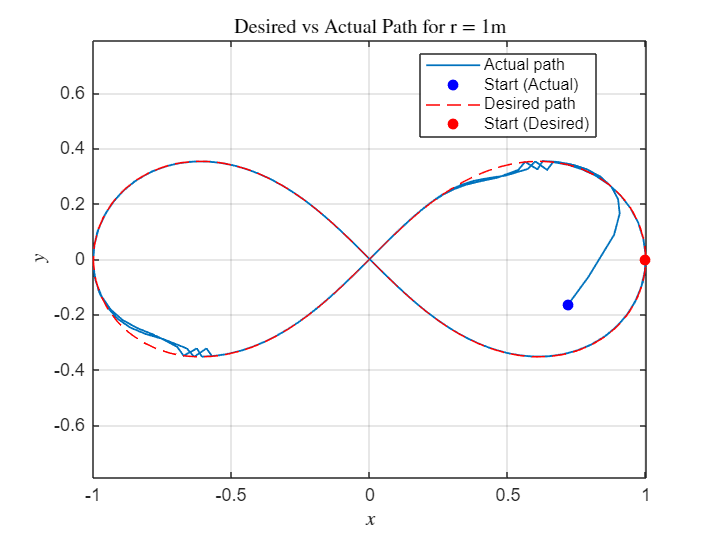


%% r = 1

figure
plot(x2, y2, 'LineWidth', 1, 'DisplayName', 'Actual path');
hold on
scatter(x2(1), y2(1), 'blue', 'filled', 'DisplayName', 'Start (Actual)');
plot(xd_all(2,:), yd_all(2,:), 'r--', 'LineWidth', 0.5, 'DisplayName', 'Desired path');
scatter(xd_all(2,1), yd_all(2,1), 'red', 'filled', 'DisplayName', 'Start (Desired)');
xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
grid on
axis equal
legend('Location','best')
title('Desired vs Actual Path for r = 1m','Interpreter','latex')
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'des_actual_2.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

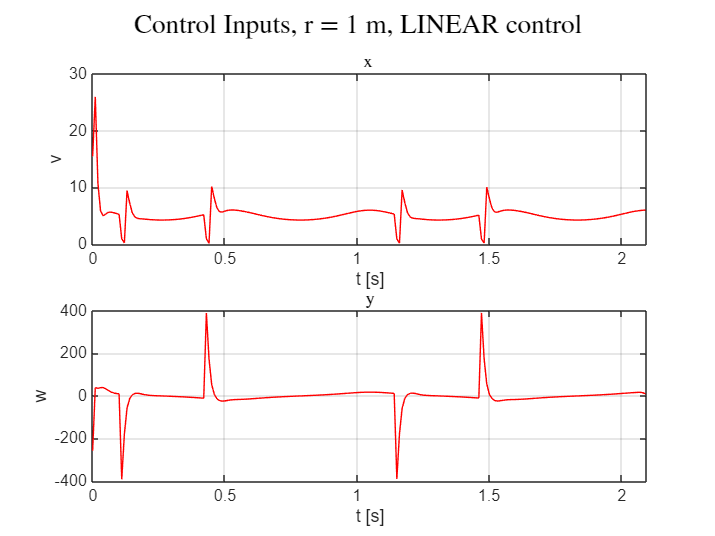

figure
sgtitle ('Control Inputs, r = 1 m, LINEAR control','Interpreter','latex')
subplot(2,1,1)
plot(t, squeeze(v2), 'r', 'LineWidth', 0.5); hold on;
title(' x ','Interpreter','latex');
xlabel('t [s]'); ylabel('v'); grid on; 
xlim([0 Tf]);
subplot(2,1,2)
plot(t, squeeze(w2), 'r', 'LineWidth', 0.5); hold on;
title('y','Interpreter','latex');
xlabel('t [s]'); ylabel('w'); grid on; 
xlim([0 Tf]);
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'inputs2.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

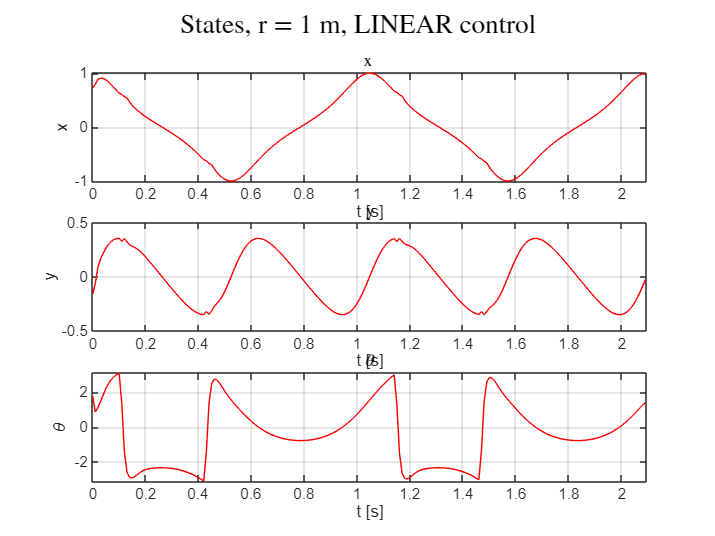


figure
sgtitle ('States, r = 1 m, LINEAR control','Interpreter','latex')
subplot(3,1,1)
plot(t, squeeze(x2), 'r', 'LineWidth', 0.5); hold on;
title(' x ','Interpreter','latex');
xlabel('t [s]'); ylabel('x'); grid on; 
xlim([0 Tf]);
subplot(3,1,2)
plot(t, squeeze(y2), 'r', 'LineWidth', 0.5); hold on;
title('y','Interpreter','latex');
xlabel('t [s]'); ylabel('y'); grid on; 
xlim([0 Tf]);
subplot(3,1,3)
plot(t, squeeze(theta2), 'r', 'LineWidth', 0.5); hold on;
title('$\theta$','Interpreter','latex');
xlabel('t [s]'); ylabel('\theta'); grid on; 
xlim([0 Tf]);
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'states2.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

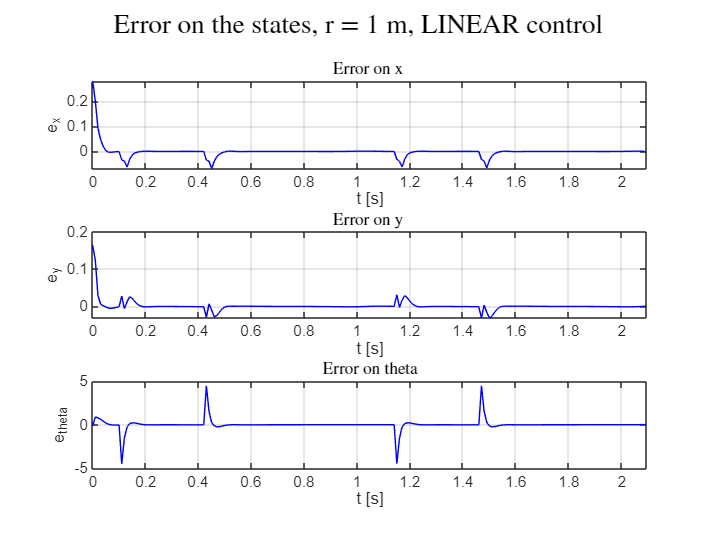


figure
sgtitle ('Error on the states, r = 1 m, LINEAR control','Interpreter','latex')
subplot(3,1,1)
plot(t, squeeze(ex2), 'b', 'LineWidth', 0.5); hold on;
title('Error on x ','Interpreter','latex');
xlabel('t [s]'); ylabel('e_x'); grid on; 
xlim([0 Tf]);
subplot(3,1,2)
plot(t, squeeze(ey2), 'b', 'LineWidth', 0.5); hold on;
title('Error on y ','Interpreter','latex');
xlabel('t [s]'); ylabel('e_y'); grid on; 
xlim([0 Tf]);
subplot(3,1,3)
plot(t, squeeze(etheta2), 'b', 'LineWidth', 0.5); hold on;
title('Error on theta','Interpreter','latex');
xlabel('t [s]'); ylabel('e_{theta}'); grid on; 
xlim([0 Tf]);
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'error2.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

(ALMOST) NONLINEAR CONTROL

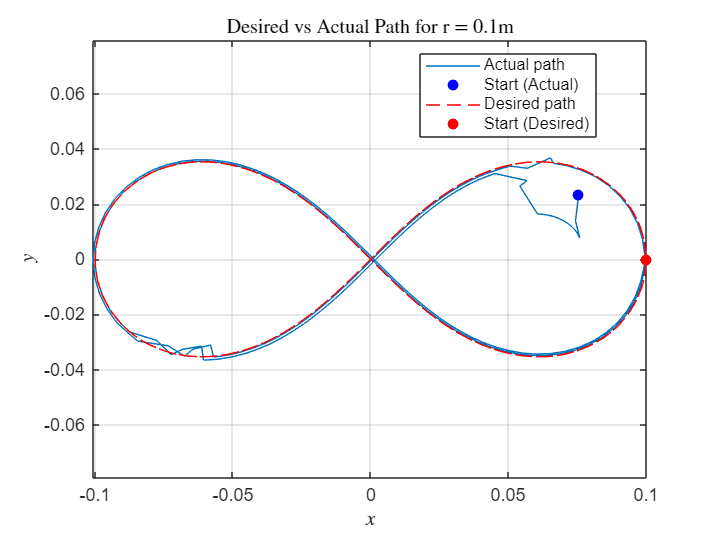

% out = sim('ex3_linear_nonlinear_control.slx');

x3 = out.x_sim3.data;
y3 = out.y_sim3.data;
theta3 = out.theta_sim3.data;
v3 = out.v3.data;
w3 = out.w3.data;

gains3 = squeeze(out.gains3.data);
gains3_1 = gains3(1,:);
gains3_2 = gains3(2,:);
gains3_3 = gains3(3,:);

exx3 = out.ex_sim3.data;
ey3 = out.ey_sim3.data;
etheta3 = out.etheta_sim3.data;

x4 = out.x_sim4.data;
y4 = out.y_sim4.data;
theta4 = out.theta_sim4.data;
v4 = out.v4.data;
w4 = out.w4.data;

gains4 = squeeze(out.gains4.data);
gains4_1 = gains4(1,:);
gains4_2 = gains4(2,:);
gains4_3 = gains4(3,:);

ex4 = out.ex_sim4.data;
ey4 = out.ey_sim4.data;
etheta4 = out.etheta_sim4.data;


%% r = 0.1

figure
plot(x3, y3, 'LineWidth', 0.5, 'DisplayName', 'Actual path');
hold on
scatter(x3(1), y3(1), 'blue', 'filled', 'DisplayName', 'Start (Actual)');
plot(xd_all(1,:), yd_all(1,:), 'r--', 'LineWidth', 0.5, 'DisplayName', 'Desired path');
scatter(xd_all(1,1), yd_all(1,1), 'red', 'filled', 'DisplayName', 'Start (Desired)');
xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
grid on
axis equal
legend('Location','best')
title('Desired vs Actual Path for r = 0.1m','Interpreter','latex')
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'des_actual_3.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

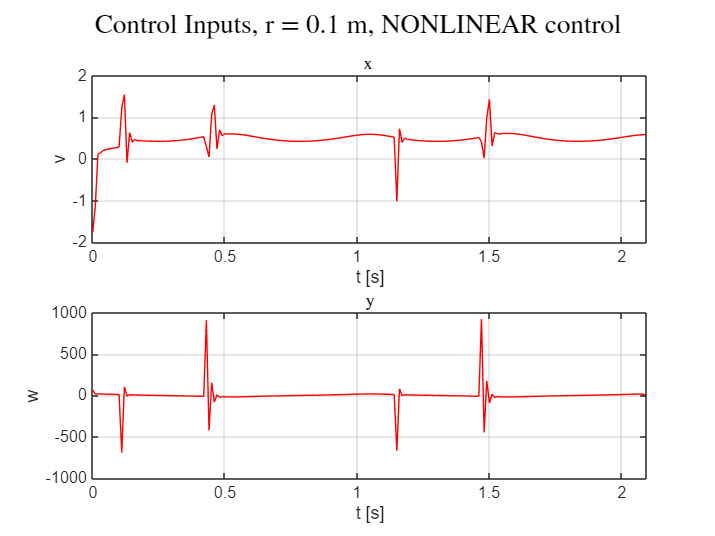

figure
sgtitle ('Control Inputs, r = 0.1 m, NONLINEAR control','Interpreter','latex')
subplot(2,1,1)
plot(t, squeeze(v3), 'r', 'LineWidth', 0.5); hold on;
title(' x ','Interpreter','latex');
xlabel('t [s]'); ylabel('v'); grid on; 
xlim([0 Tf]);
subplot(2,1,2)
plot(t, squeeze(w3), 'r', 'LineWidth', 0.5); hold on;
title('y','Interpreter','latex');
xlabel('t [s]'); ylabel('w'); grid on; 
xlim([0 Tf]);
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'inputs3.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

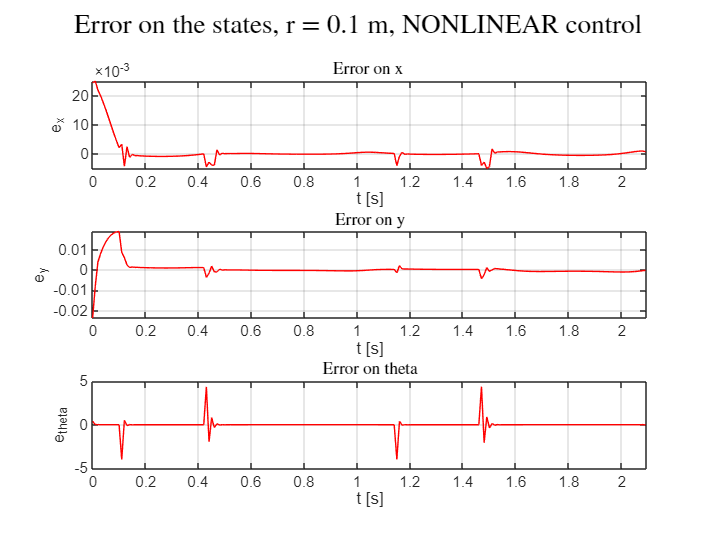


figure
sgtitle ('Error on the states, r = 0.1 m, NONLINEAR control','Interpreter','latex')
subplot(3,1,1)
plot(t, squeeze(exx3), 'r', 'LineWidth', 0.5); hold on;
title('Error on x ','Interpreter','latex');
xlabel('t [s]'); ylabel('e_x'); grid on; 
xlim([0 Tf]);
subplot(3,1,2)
plot(t, squeeze(ey3), 'r', 'LineWidth', 0.5); hold on;
title('Error on y','Interpreter','latex');
xlabel('t [s]'); ylabel('e_y'); grid on; 
xlim([0 Tf]);
subplot(3,1,3)
plot(t, squeeze(etheta3), 'r', 'LineWidth', 0.5); hold on;
title('Error on theta','Interpreter','latex');
xlabel('t [s]'); ylabel('e_{theta}'); grid on; 
xlim([0 Tf]);
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'error3.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

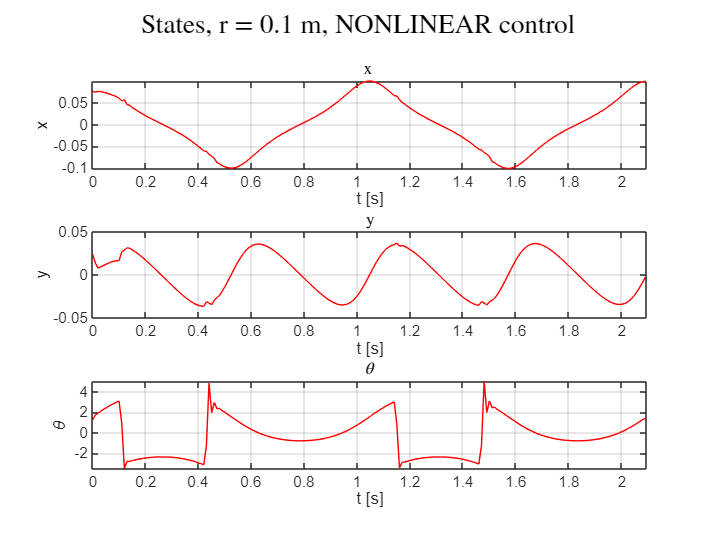


figure
sgtitle ('States, r = 0.1 m, NONLINEAR control','Interpreter','latex')
subplot(3,1,1)
plot(t, squeeze(x3), 'r', 'LineWidth', 0.5); hold on;
title(' x ','Interpreter','latex');
xlabel('t [s]'); ylabel('x'); grid on; 
xlim([0 Tf]);
subplot(3,1,2)
plot(t, squeeze(y3), 'r', 'LineWidth', 0.5); hold on;
title('y','Interpreter','latex');
xlabel('t [s]'); ylabel('y'); grid on; 
xlim([0 Tf]);
subplot(3,1,3)
plot(t, squeeze(theta3), 'r', 'LineWidth', 0.5); hold on;
title('$\theta$','Interpreter','latex');
xlabel('t [s]'); ylabel('\theta'); grid on; 
xlim([0 Tf]);
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'states3.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

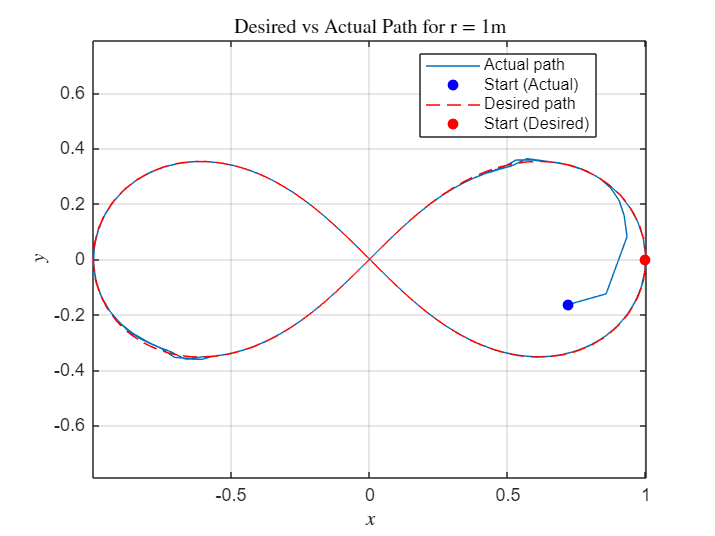


%% r = 1

figure
plot(x4, y4, 'LineWidth', 0.5, 'DisplayName', 'Actual path');
hold on
scatter(x4(1), y4(1), 'blue', 'filled', 'DisplayName', 'Start (Actual)');
plot(xd_all(2,:), yd_all(2,:), 'r--', 'LineWidth', 0.5, 'DisplayName', 'Desired path');
scatter(xd_all(2,1), yd_all(2,1), 'red', 'filled', 'DisplayName', 'Start (Desired)');
xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
grid on
axis equal
legend('Location','best')
title('Desired vs Actual Path for r = 1m','Interpreter','latex')
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'des_actual_4.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

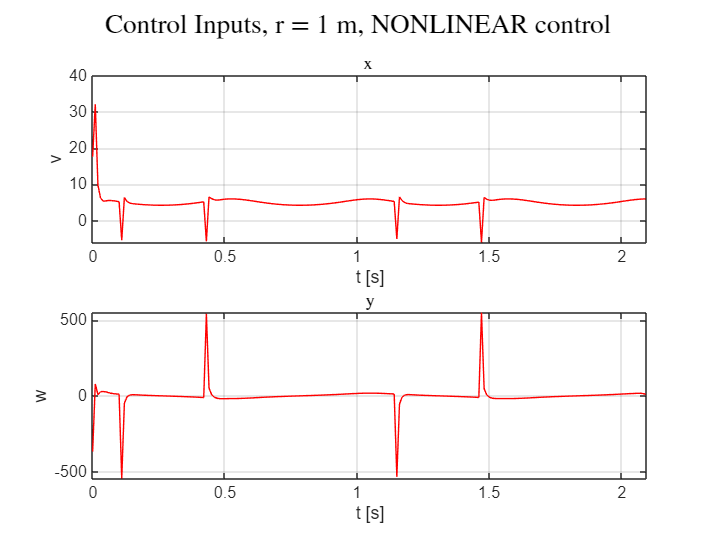


figure
sgtitle ('Control Inputs, r = 1 m, NONLINEAR control','Interpreter','latex')
subplot(2,1,1)
plot(t, squeeze(v4), 'r', 'LineWidth', 0.5); hold on;
title(' x ','Interpreter','latex');
xlabel('t [s]'); ylabel('v'); grid on; 
xlim([0 Tf]);
subplot(2,1,2)
plot(t, squeeze(w4), 'r', 'LineWidth', 0.5); hold on;
title('y','Interpreter','latex');
xlabel('t [s]'); ylabel('w'); grid on; 
xlim([0 Tf]);
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'inputs4.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

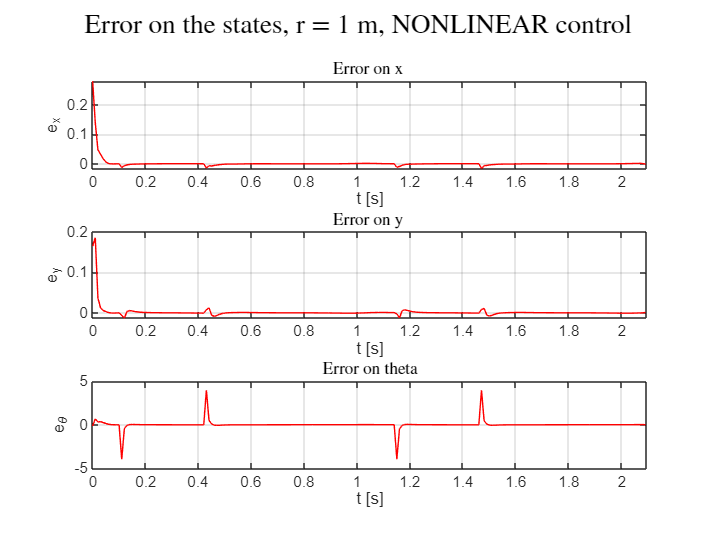


figure
sgtitle ('Error on the states, r = 1 m, NONLINEAR control','Interpreter','latex')
subplot(3,1,1)
plot(t, squeeze(ex4), 'r', 'LineWidth', 0.5); hold on;
title('Error on x ','Interpreter','latex');
xlabel('t [s]'); ylabel('e_x'); grid on; 
xlim([0 Tf]);
subplot(3,1,2)
plot(t, squeeze(ey4), 'r', 'LineWidth', 0.5); hold on;
title('Error on y ','Interpreter','latex');
xlabel('t [s]'); ylabel('e_y'); grid on; 
xlim([0 Tf]);
subplot(3,1,3)
plot(t, squeeze(etheta4), 'r', 'LineWidth', 0.5); hold on;
title('Error on theta','Interpreter','latex');
xlabel('t [s]'); ylabel('e_{\theta}'); grid on; 
xlim([0 Tf]);
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'error4.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

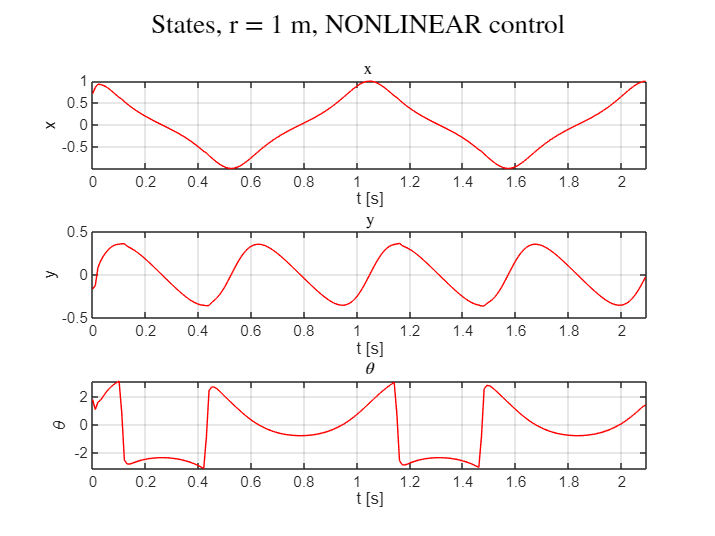


figure
sgtitle ('States, r = 1 m, NONLINEAR control','Interpreter','latex')
subplot(3,1,1)
plot(t, squeeze(x4), 'r', 'LineWidth', 0.5); hold on;
title(' x ','Interpreter','latex');
xlabel('t [s]'); ylabel('x'); grid on; 
xlim([0 Tf]);
subplot(3,1,2)
plot(t, squeeze(y4), 'r', 'LineWidth', 0.5); hold on;
title('y','Interpreter','latex');
xlabel('t [s]'); ylabel('y'); grid on; 
xlim([0 Tf]);
subplot(3,1,3)
plot(t, squeeze(theta4), 'r', 'LineWidth', 0.5); hold on;
title('$\theta$','Interpreter','latex');
xlabel('t [s]'); ylabel('\theta'); grid on; 
xlim([0 Tf]);
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'states4.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

COMPARISON

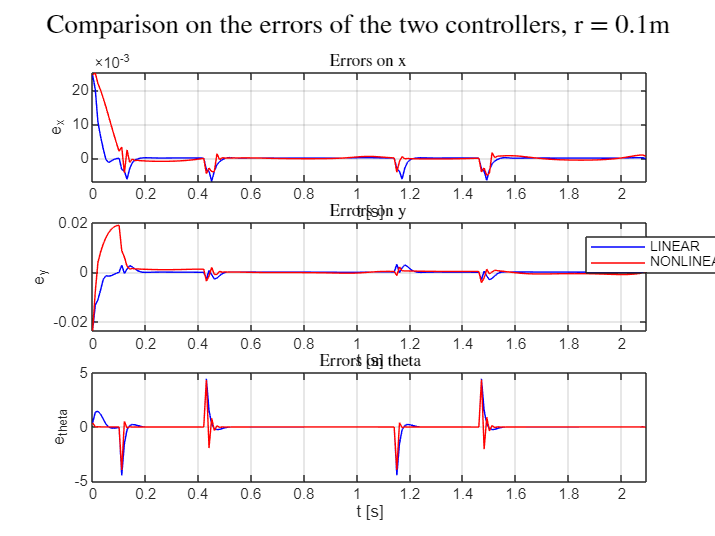

figure
sgtitle('Comparison on the errors of the two controllers, r = 0.1m','Interpreter','latex')
subplot(3,1,1)
plot(t, squeeze(ex1), 'b', 'LineWidth', 0.5,'DisplayName', 'LINEAR'); hold on;
plot(t, squeeze(exx3), 'r', 'LineWidth', 0.5,'DisplayName', 'NONLINEAR'); hold on;
title('Errors on x ','Interpreter','latex');
xlabel('t [s]'); ylabel('e_x'); grid on; 
xlim([0 Tf]);
subplot(3,1,2)
plot(t, squeeze(ey1), 'b', 'LineWidth', 0.5,'DisplayName', 'LINEAR'); hold on;
plot(t, squeeze(ey3), 'r', 'LineWidth', 0.5,'DisplayName', 'NONLINEAR'); hold on;
title('Errors on y ','Interpreter','latex');
xlabel('t [s]'); ylabel('e_y'); grid on; 
xlim([0 Tf]);
subplot(3,1,3)
plot(t, squeeze(etheta1), 'b', 'LineWidth', 0.5,'DisplayName', 'LINEAR'); hold on;
plot(t, squeeze(etheta3), 'r', 'LineWidth', 0.5,'DisplayName', 'NONLINEAR'); hold on;
title('Errors on theta','Interpreter','latex');
xlabel('t [s]'); ylabel('e_{theta}'); grid on; 
xlim([0 Tf]);
legend('Location',[0.9 0.5 0.05 0.05])
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'comp_error1.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

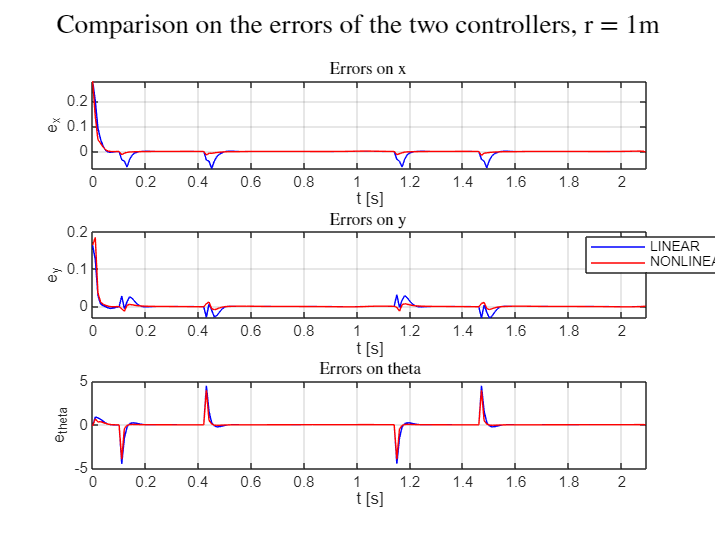



figure
sgtitle('Comparison on the errors of the two controllers, r = 1m','Interpreter','latex')
subplot(3,1,1)
plot(t, squeeze(ex2), 'b', 'LineWidth', 0.5,'DisplayName', 'LINEAR'); hold on;
plot(t, squeeze(ex4), 'r', 'LineWidth', 0.5,'DisplayName', 'NONLINEAR'); hold on;
title('Errors on x ','Interpreter','latex');
xlabel('t [s]'); ylabel('e_x'); grid on; 
xlim([0 Tf]);
subplot(3,1,2)
plot(t, squeeze(ey2), 'b', 'LineWidth', 0.5,'DisplayName', 'LINEAR'); hold on;
plot(t, squeeze(ey4), 'r', 'LineWidth', 0.5,'DisplayName', 'NONLINEAR'); hold on;
title('Errors on y ','Interpreter','latex');
xlabel('t [s]'); ylabel('e_y'); grid on; 
xlim([0 Tf]);
subplot(3,1,3)
plot(t, squeeze(etheta2), 'b', 'LineWidth', 0.5,'DisplayName', 'LINEAR'); hold on;
plot(t, squeeze(etheta4), 'r', 'LineWidth', 0.5,'DisplayName', 'NONLINEAR'); hold on;
title('Errors on theta','Interpreter','latex');
xlabel('t [s]'); ylabel('e_{theta}'); grid on; 
xlim([0 Tf]);
legend('Location',[0.9 0.5 0.05 0.05])
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'comp_error2.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

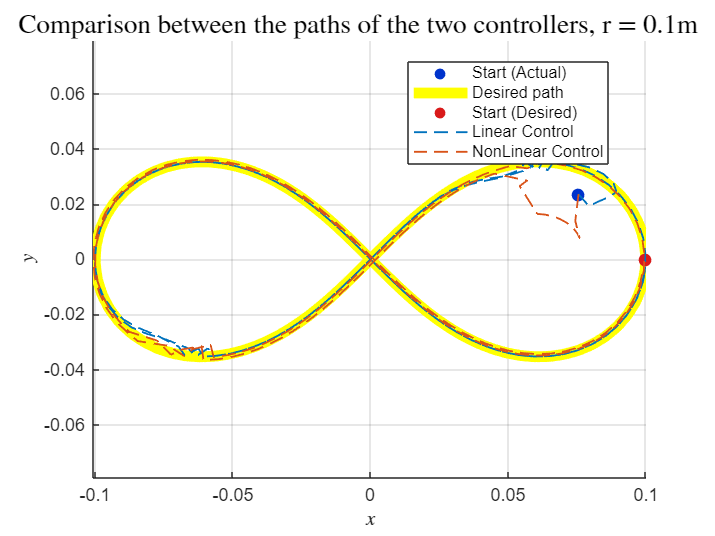


figure
sgtitle('Comparison between the paths of the two controllers, r = 0.1m','Interpreter','latex')
scatter(x3(1), y3(1), 50, [0 0.2 0.8], 'filled', 'DisplayName', 'Start (Actual)'); hold on;
plot(xd_all(1,:), yd_all(1,:),  'y', 'LineWidth', 6, 'DisplayName', 'Desired path'); hold on;
scatter(xd_all(1,1), yd_all(1,1), 50, [0.85 0.1 0.1], 'filled', 'DisplayName', 'Start (Desired)'); hold on;
plot(x1, y1,'--', 'Color', [0 0.4470 0.7410], 'LineWidth', 1, 'DisplayName', 'Linear Control'); hold on;
plot(x3, y3,'--', 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 1, 'DisplayName', 'NonLinear Control'); hold on;
xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
grid on
axis equal
legend('Location','best')
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'comp_path1.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

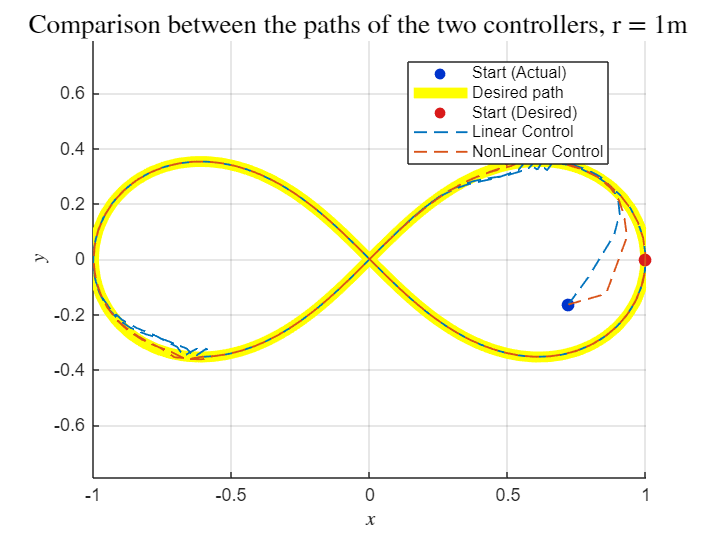


figure
sgtitle('Comparison between the paths of the two controllers, r = 1m','Interpreter','latex')
scatter(x4(1), y4(1), 50, [0 0.2 0.8], 'filled', 'DisplayName', 'Start (Actual)'); hold on;
plot(xd_all(2,:), yd_all(2,:),  'y', 'LineWidth', 6, 'DisplayName', 'Desired path'); hold on;
scatter(xd_all(2,1), yd_all(2,1), 50, [0.85 0.1 0.1], 'filled', 'DisplayName', 'Start (Desired)'); hold on;
plot(x2, y2,'--', 'Color', [0 0.4470 0.7410], 'LineWidth', 1, 'DisplayName', 'Linear Control'); hold on;
plot(x4, y4,'--', 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 1, 'DisplayName', 'NonLinear Control'); hold on;
xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
grid on
axis equal
legend('Location','best')
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'comp_path2.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

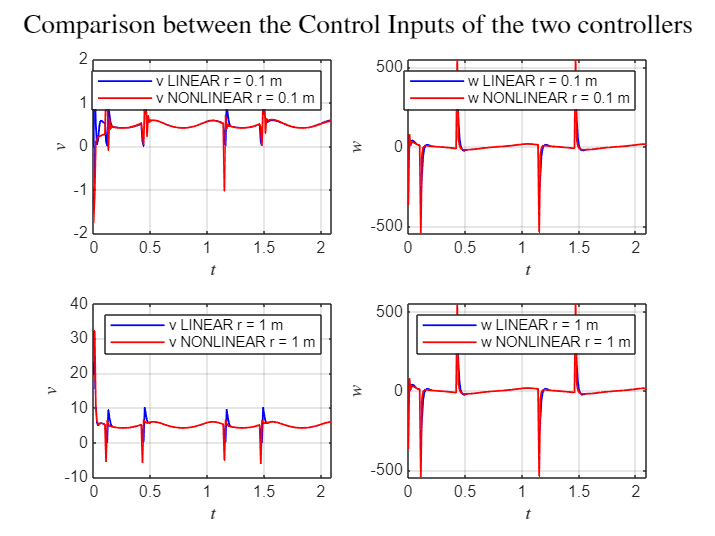


figure
subplot(2,2,1)
plot(t, v1,  'b', 'LineWidth', 1, 'DisplayName', 'v LINEAR r = 0.1 m'); hold on;
plot(t, v3,  'r', 'LineWidth', 1, 'DisplayName', 'v NONLINEAR r = 0.1 m'); 
xlabel('$t$','Interpreter','latex')
ylabel('$v$','Interpreter','latex')
grid on
legend
xlim([0 Tf]);
subplot(2,2,2)
plot(t, w2,  'b', 'LineWidth', 1, 'DisplayName', 'w LINEAR r = 0.1 m'); hold on;
plot(t, w4,  'r', 'LineWidth', 1, 'DisplayName', 'w NONLINEAR r = 0.1 m'); 
xlabel('$t$','Interpreter','latex')
ylabel('$w$','Interpreter','latex')
grid on
legend
xlim([0 Tf]);
subplot(2,2,3)
plot(t, v2,  'b', 'LineWidth', 1, 'DisplayName', 'v LINEAR r = 1 m'); hold on;
plot(t, v4,  'r', 'LineWidth', 1, 'DisplayName', 'v NONLINEAR r = 1 m'); 
xlabel('$t$','Interpreter','latex')
ylabel('$v$','Interpreter','latex')
grid on
legend
xlim([0 Tf]);
subplot(2,2,4)
title('r = 1 m','Interpreter','latex')
plot(t, w2,  'b', 'LineWidth', 1, 'DisplayName', 'w LINEAR r = 1 m'); hold on;
plot(t, w4,  'r', 'LineWidth', 1, 'DisplayName', 'w NONLINEAR r = 1 m'); 
xlabel('$t$','Interpreter','latex')
ylabel('$w$','Interpreter','latex')
grid on
legend
xlim([0 Tf]);
sgtitle('Comparison between the Control Inputs of the two controllers','Interpreter','latex')
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'comp_inputs.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

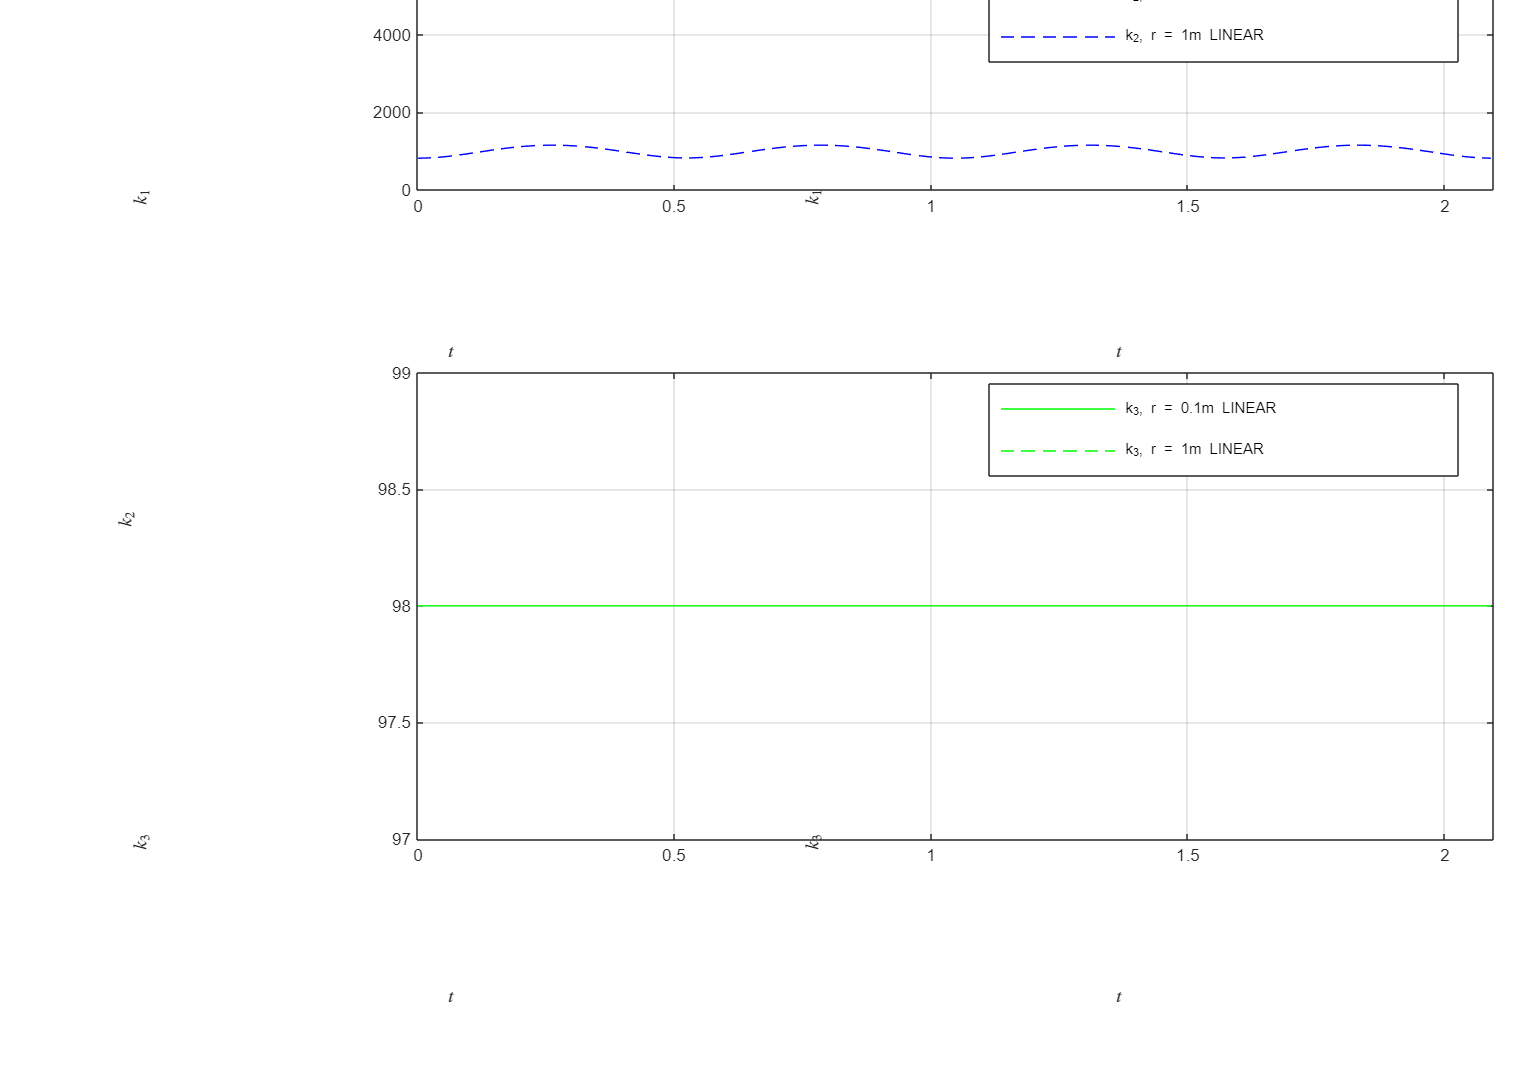


figure
set(gcf, 'Units', 'inches', 'Position', [1, 1, 11.7, 8.3]);
subplot(3,2,1)
plot(t, gains1_1, 'r', 'LineWidth', 0.5, 'DisplayName','k_1, r = 0.1m LINEAR'); hold on;
plot(t, gains2_1, 'r--', 'LineWidth', 0.5, 'DisplayName','k_1, r = 1m LINEAR'); hold on;
xlabel('$t$','Interpreter','latex')
ylabel('$k_1$','Interpreter','latex')
grid on; 
xlim([0 Tf]);
legend('Location','best')
subplot(3,2,2)
plot(t, gains3_1, 'r', 'LineWidth', 0.5, 'DisplayName','k_1, r = 0.1m NONLINEAR'); hold on;
plot(t, gains4_1, 'r--', 'LineWidth', 0.5, 'DisplayName','k_1, r = 1m NONLINEAR'); 
xlabel('$t$','Interpreter','latex')
ylabel('$k_1$','Interpreter','latex')
grid on; 
xlim([0 Tf]);
legend('Location','best')
subplot(3,2,3)
xlabel('t [s]'); ylabel('k'); grid on; 
xlim([0 Tf]);
legend('Location','best')
plot(t, gains1_2, 'b', 'LineWidth', 0.5, 'DisplayName','k_2, r = 0.1m LINEAR'); hold on;
plot(t, gains2_2, 'b--', 'LineWidth', 0.5, 'DisplayName','k_2, r = 1m LINEAR' ); 
xlabel('$t$','Interpreter','latex')
ylabel('$k_2$','Interpreter','latex')
grid on; xlim([0 Tf]);
legend('Location','best')
subplot(3,2,4)
plot(t, gains3_2, 'b', 'LineWidth', 0.5, 'DisplayName','k_2, r = 0.1m NONLINEAR'); hold on;
plot(t, gains4_2, 'b--', 'LineWidth', 0.5, 'DisplayName','k_2, r = 1m NONLINEAR'); hold on;
xlabel('$t$','Interpreter','latex')
ylabel('$k_2$','Interpreter','latex')
grid on;
xlim([0 Tf]);
legend('Location','best')
subplot(3,2,5)
plot(t, gains1_3, 'g', 'LineWidth', 0.5, 'DisplayName','k_3, r = 0.1m LINEAR'); hold on;
plot(t, gains2_3, 'g--', 'LineWidth', 0.5, 'DisplayName','k_3, r = 1m LINEAR'); 
xlabel('$t$','Interpreter','latex')
ylabel('$k_3$','Interpreter','latex')
grid on;xlim([0 Tf]);
legend('Location','best')
subplot(3,2,6)
plot(t, gains3_3, 'g', 'LineWidth', 0.5, 'DisplayName','k_3, r = 0.1m NONLINEAR'); hold on;
plot(t, gains4_3, 'g--', 'LineWidth', 0.5, 'DisplayName','k_3, r = 1m NONLINEAR'); 
xlabel('$t$','Interpreter','latex')
ylabel('$k_3$','Interpreter','latex')
grid on;xlim([0 Tf]);
legend('Location','best')
set(gcf, 'PaperPositionMode', 'auto'); 
exportgraphics(gcf, 'gains_es4_grande.pdf', ...
    'ContentType', 'vector', ...
    'BackgroundColor', 'white', ...
    'Resolution', 300);